#  Statistical Modeling Textbook: Linear Regression Model 

##  Statistical Modeling for Data Analysis #3 Practical Edition 

clear;
close all;

###  6. Practical Data Analysis: Creation of Automobile Sales Forecasting Model 

####  Standardization 

A: 

I created a linear regression model to predict car fuel efficiency, but now I would like to use what I learned to predict sales.'' 

B: 

``What should we do first?'' 

A: 

``It's standardization/normalization. The normalized data is already prepared in the following Excel lol'' 

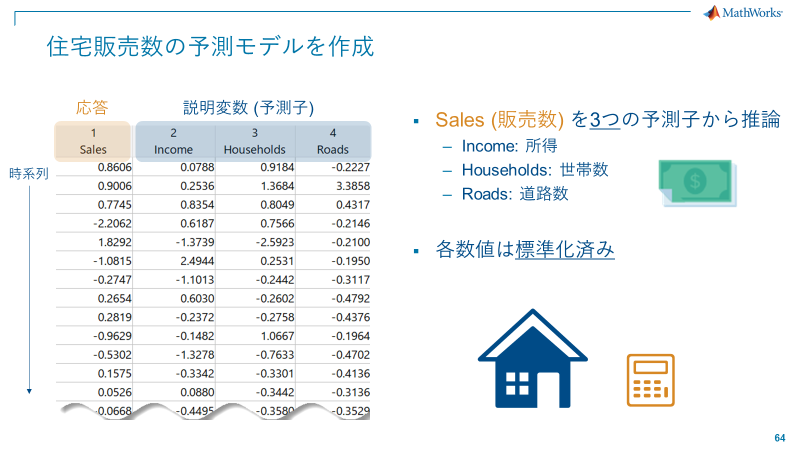

carSales = readtable("carSales.xlsx");
head(carSales) 

     Sales      Income     Households     Roads  
    ________    _______    __________    ________
     0.86056    0.07876      0.91835     -0.22272
     0.90064    0.25359       1.3684       3.3858
      0.7745    0.83541      0.80495      0.43167
     -2.2062    0.61872      0.75664     -0.21461
      1.8292    -1.3739      -2.5923     -0.20996
     -1.0815     2.4944       0.2531     -0.19501
    -0.27467    -1.1013     -0.24422      -0.3117
     0.26539    0.60302     -0.26018     -0.47925


A: 

``Let's regress automobile sales from Income, Households, and Roads. ” 

B: 

“Let's check it out. It's the average value and standard deviation.” 

mean(carSales.Variables,1)

ans = 1.0e-15 *

    0.0753   -0.1308   -0.1150   -0.0436


std(carSales.Variables,0,1) 

ans =     1.0000    1.0000    1.0000    1.0000


A: 

“Okay! I wonder what the second argument of std is...” 

B: 

"It's an option between the so-called invariant variance and the sample variance. The expected value of the sample variance is 


$$\mathbb{E}\left[\frac{1}{n}\sum_{i=1}^n (x_i - \bar{x})^2\right] = \frac{n-1}{n}\sigma^2$$


, so it's not an invariant estimator. Here, the option is 0, so the invariant variance 


$$\frac{1}{n-1}\sum_{i=1}^n (x_i - \bar{x})^2 $$


####  Checking for multicollinearity 

B: 

``Okay, what do we do next?'' 

A: 

``Checking for multicollinearity (multicollinearity) )" 

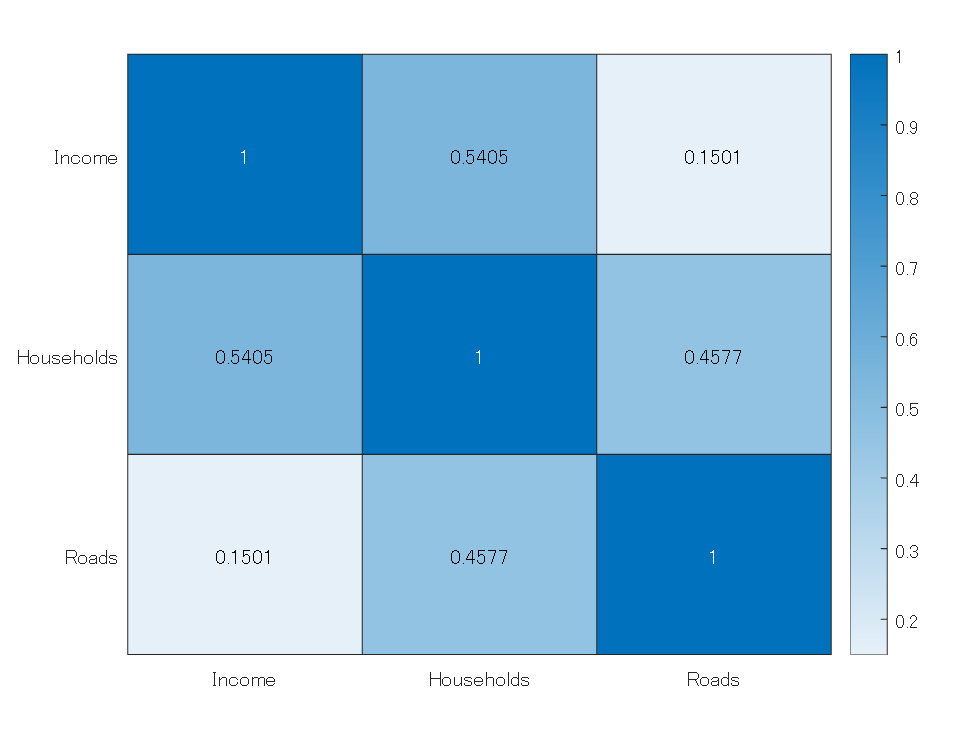

corrTbl = corrcoef(table2array(carSales(:,2:end)));
heatmap(corrTbl,"XData",{'Income', 'Households', 'Roads'},"YData",{'Income', 'Households', 'Roads'}); 

A: 

"The correlation between the predictors is not that high, so I think we can use it as is!" 

B: 

"By the way, if you have Econometrics Toolbox™, you can do something like this. You can also see the correlation in the wind.'' 

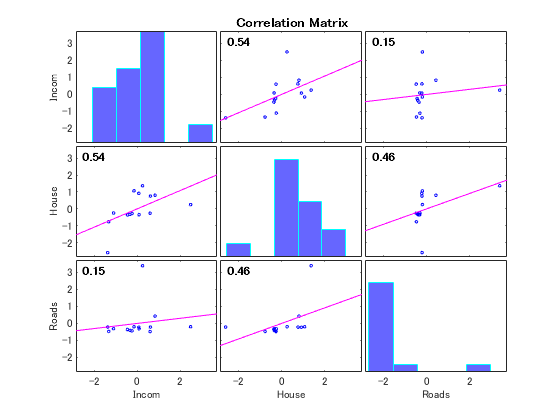

B: 

``Then, let's create a model right away (smirking)'' 

#### ** Multiple regression **

A: 

``As usual...'' 

mdl_carSales = fitlm(carSales, "Sales ~ 1 + Income + Households + Roads");
disp(mdl_carSales); 

線形回帰モデル: 
    Sales ~ 1 + Income + Households + Roads

推定された係数: 
                    Estimate        SE          tStat        pValue 
                   ___________    _______    ___________    ________
    (Intercept)    -7.4136e-17     0.2348    -3.1574e-16           1
    Income            -0.12104     0.2921       -0.41437     0.68735
    Households        -0.55874    0.32481        -1.7202     0.11613
    Roads              0.55914    0.27641         2.0229    0.070641

観測数: 14、誤差の自由度: 10
平方根平均二乗誤差: 0.879
決定係数: 0.406、自由度調整済み決定係数: 0.228
F 統計量 - 定数モデルとの比較: 2.28、p 値は 0.142 です


A: 

``The p-value is large!!... Income and Households have no relation to Sales?! Hmm, that's a little different from what I expected... I feel like something is wrong.''.'' 

B: 

``Since it is expected that there is a clear correlation between the number of automobile sales and residents' income, why not look at the temporal cross-correlation here?'' 

A : 

"Huh?... Cross-correlation?" 

####  Question 6.1: What is cross-correlation? 

** Answer: ** Correlation between signals (along the time axis) 


$$C_{xy}(m) = \left\{
\begin{array}{ll}
\sum_n x_{n+m}\cdot y_n & (m \geq 0)\\
\sum_n y_{n-m} \cdot x_n & (m < 0)
\end{array}
\right.
$$


Similar to Convolution However, the calculation is slightly different. Express the similarity of two signals along lag m 

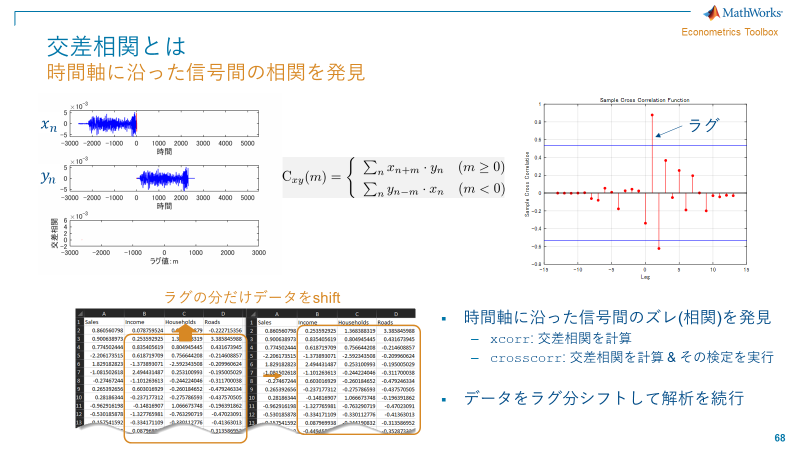

The calculation image is below. A peak occurs where the two signals overlap strongly. 

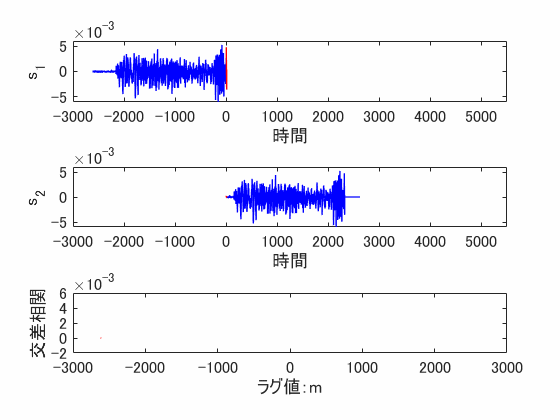

A: 

"Is that so? Because the number of cars sold and the income of residents were out of chronological order, they were not reflected well in the model!" 

B: 

"This is what Domain Knowledge does. That's right. You should make full use of the common sense you've cultivated in your specialized field." 

"Now, let's use the function xcorr to calculate the deviation." 

### ** 7. Cross-correlation **

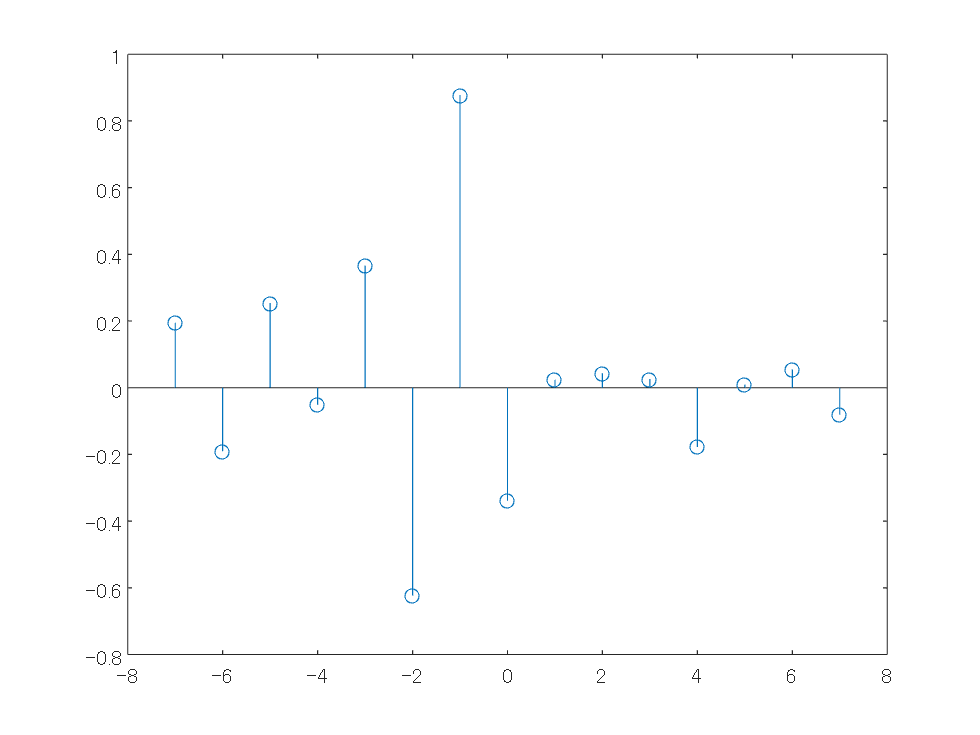

sales = carSales.Sales; %
income = carSales.Income;

% Cross correlation
[cr, lags] = xcorr(sales, income, 7, 'normalized');
stem(lags, cr); 

A: 

``When I looked at the peak, I found that there was one lag.'' 

B: 

``Incidentally, this kind of issue is often considered in financial engineering, so if you use Econometrics Toolbox, In an instant...." 

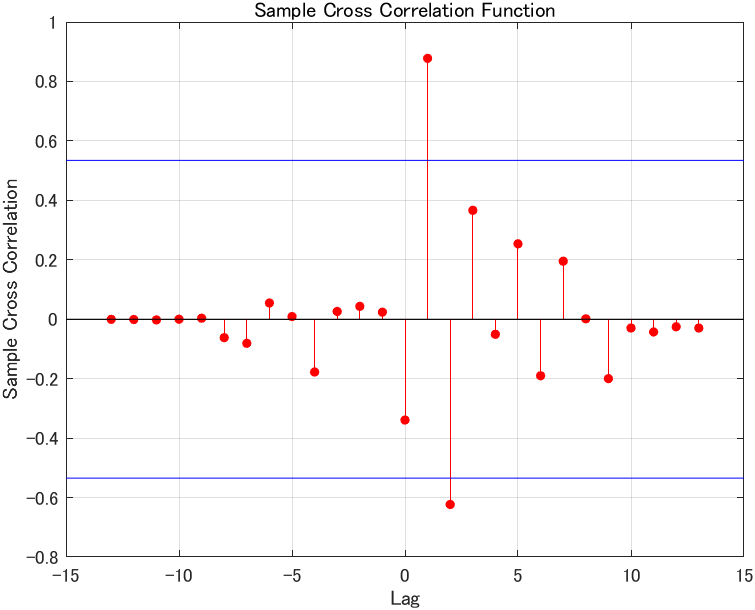

A: 

"What is the blue line?" 

B: 

"This is a test of cross-correlation. The 5% significance level line is the default value. It is significant when Lag = 1.'' 

A: 

``It's convenient that you even test it.'' 

``Now, let's shift the data by one so that the model can be created successfully.'' 

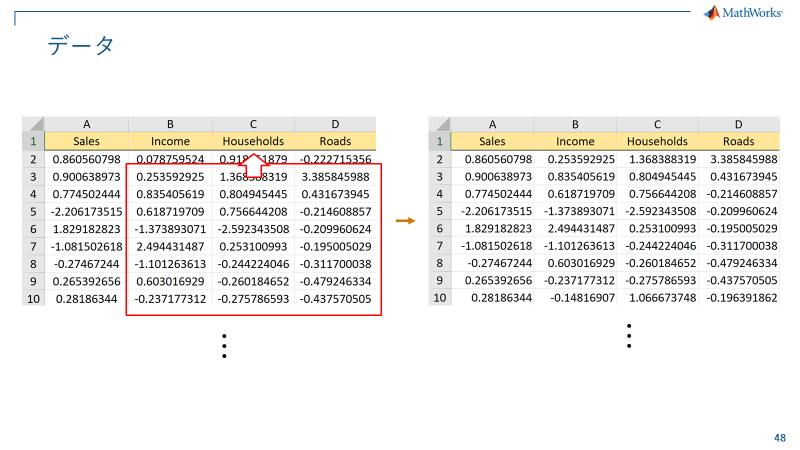

####  Eliminate cross-correlation 

** Load data shifted by one (prepared in advance with Excel operations) **

carSales_Shift = readtable("carSales_Shift.xlsx");
mdl_carSales_Shift = fitlm(carSales_Shift, "Sales ~ 1 + Income + Households + Roads");
disp(mdl_carSales_Shift);

線形回帰モデル: 
    Sales ~ 1 + Income + Households + Roads

推定された係数: 
                    Estimate       SE         tStat        pValue  
                   __________    _______    _________    __________
    (Intercept)      0.042522    0.09708      0.43801        0.6717
    Income            0.62424    0.11766       5.3056    0.00049024
    Households         0.4753    0.13857         3.43     0.0075085
    Roads          -0.0015437    0.11277    -0.013689       0.98938

観測数: 13、誤差の自由度: 9
平方根平均二乗誤差: 0.348
決定係数: 0.916、自由度調整済み決定係数: 0.888
F 統計量 - 定数モデルとの比較: 32.8、p 値は 3.57e-05 です


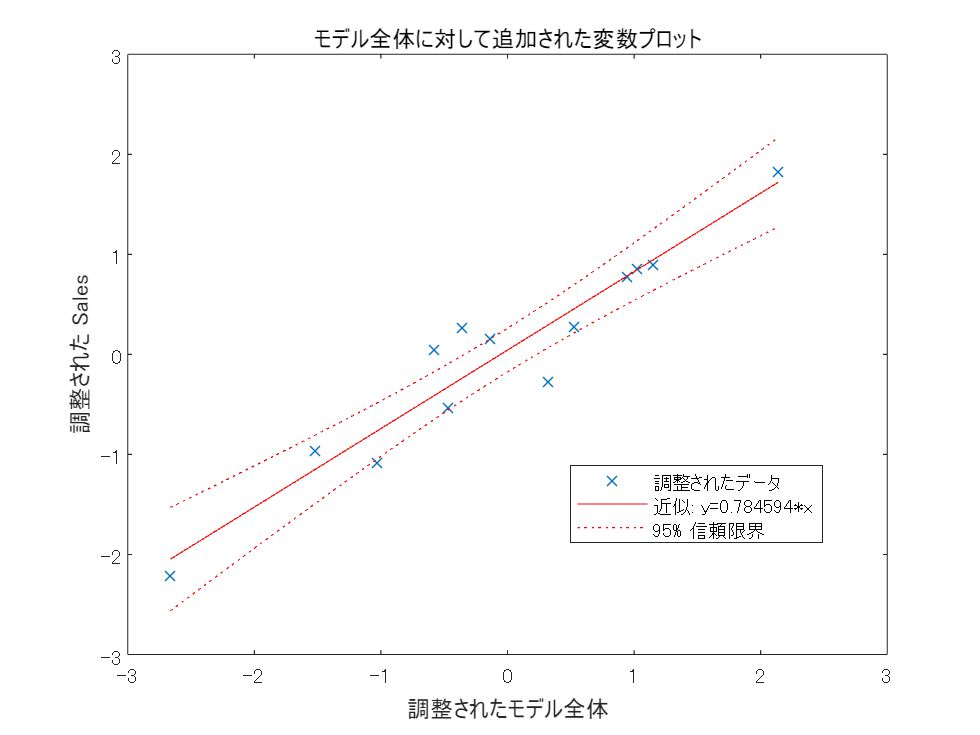

plot(mdl_carSales_Shift);

** Hint: ** Two-dimensional plot of multiple regression - Frisch–Waugh–Lovell theorem 

A: 

Wow! It's improved!!" 

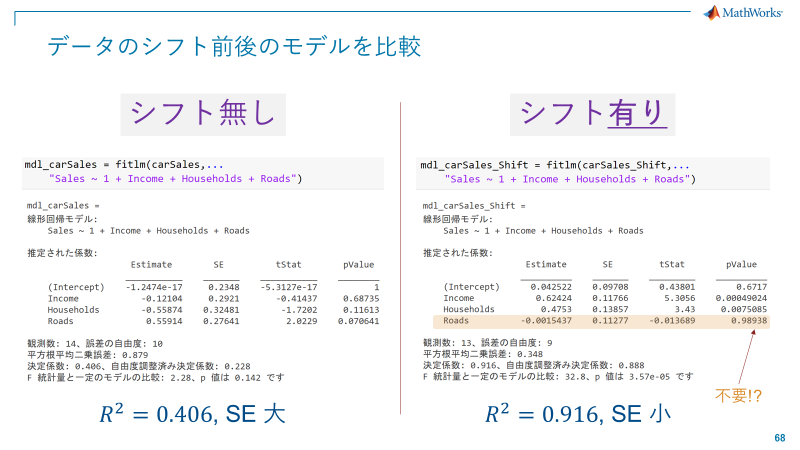

B: 

"It went well.The various statistics seem to be healthy, and the sign of the coefficient is not bad.Looking at the p-value, the paved road may not have much to do with it. Since I don't know, I think it's okay to remove it." 

mdl_carSales_Shift2 = fitlm(carSales_Shift, "Sales ~ 1 + Income + Households");
disp(mdl_carSales_Shift2); 

線形回帰モデル: 
    Sales ~ 1 + Income + Households

推定された係数: 
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________
    (Intercept)    0.042431    0.091881    0.4618       0.65411
    Income          0.62451     0.11004    5.6754    0.00020514
    Households      0.47436     0.11407    4.1586      0.001953

観測数: 13、誤差の自由度: 10
平方根平均二乗誤差: 0.33
決定係数: 0.916、自由度調整済み決定係数: 0.899
F 統計量 - 定数モデルとの比較: 54.6、p 値は 4.15e-06 です


B: 

"Let's check the AIC." 

mdl_carSales_Shift.ModelCriterion

ans = フィールドをもつ struct :
     AIC: 12.6652
    AICc: 17.6652
     BIC: 14.9250
    CAIC: 18.9250

mdl_carSales_Shift2.ModelCriterion 

ans = フィールドをもつ struct :
     AIC: 10.6655
    AICc: 13.3321
     BIC: 12.3603
    CAIC: 15.3603

A: 

"It would be better to remove "Road"!" 

A: 

" In the end, this is what we will do.'' 

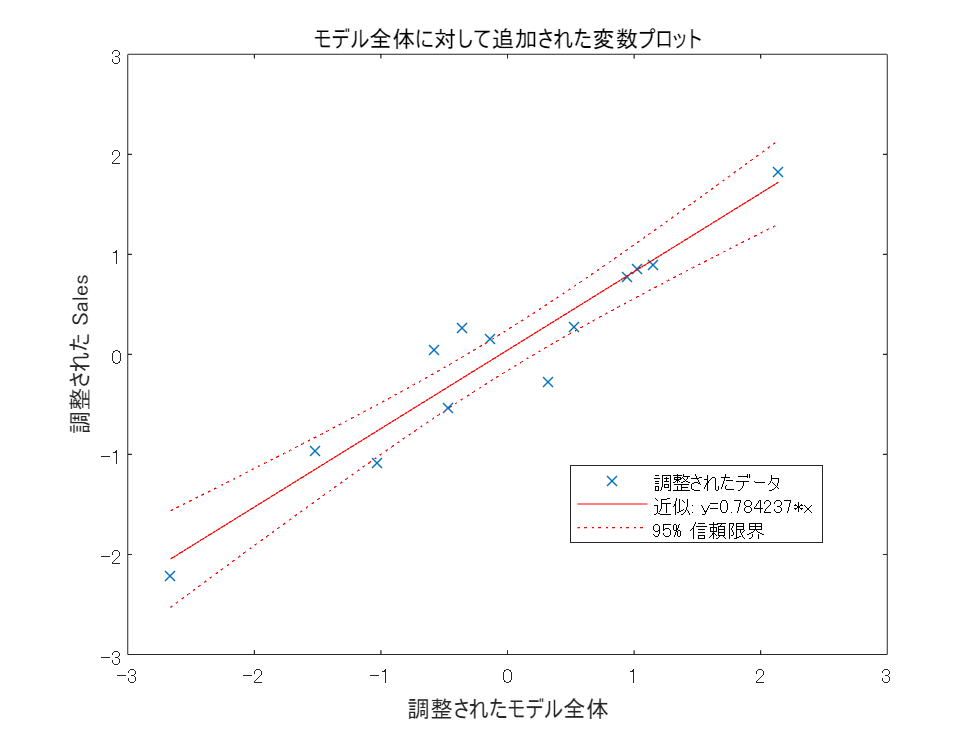

plot(mdl_carSales_Shift2);

disp(mdl_carSales_Shift2); 

線形回帰モデル: 
    Sales ~ 1 + Income + Households

推定された係数: 
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________
    (Intercept)    0.042431    0.091881    0.4618       0.65411
    Income          0.62451     0.11004    5.6754    0.00020514
    Households      0.47436     0.11407    4.1586      0.001953

観測数: 13、誤差の自由度: 10
平方根平均二乗誤差: 0.33
決定係数: 0.916、自由度調整済み決定係数: 0.899
F 統計量 - 定数モデルとの比較: 54.6、p 値は 4.15e-06 です


B: 

``Thank you for your hard work! Please read the summary of points carefully and review!'' 

A: 

``Linear regression is quite deep... Isn't there an easy way to create various regression models..." 

B: 

"Well, let me tell you that in here!" 

##  Summary of points 4 

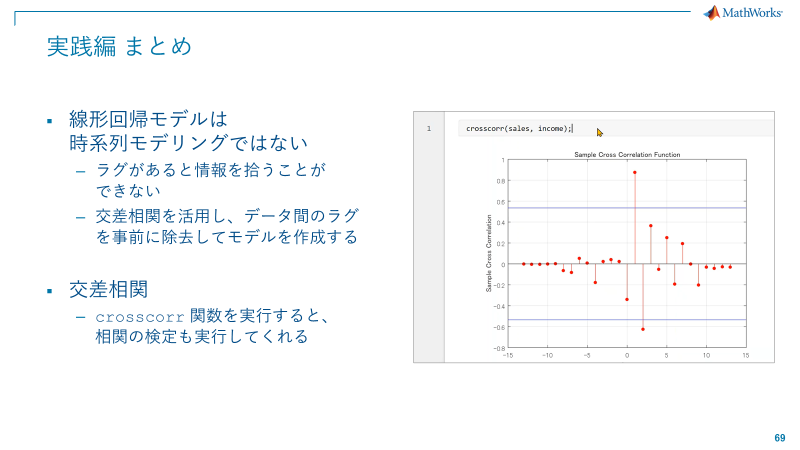

##  Appendix: Machine learning app 

regressionLearner; 

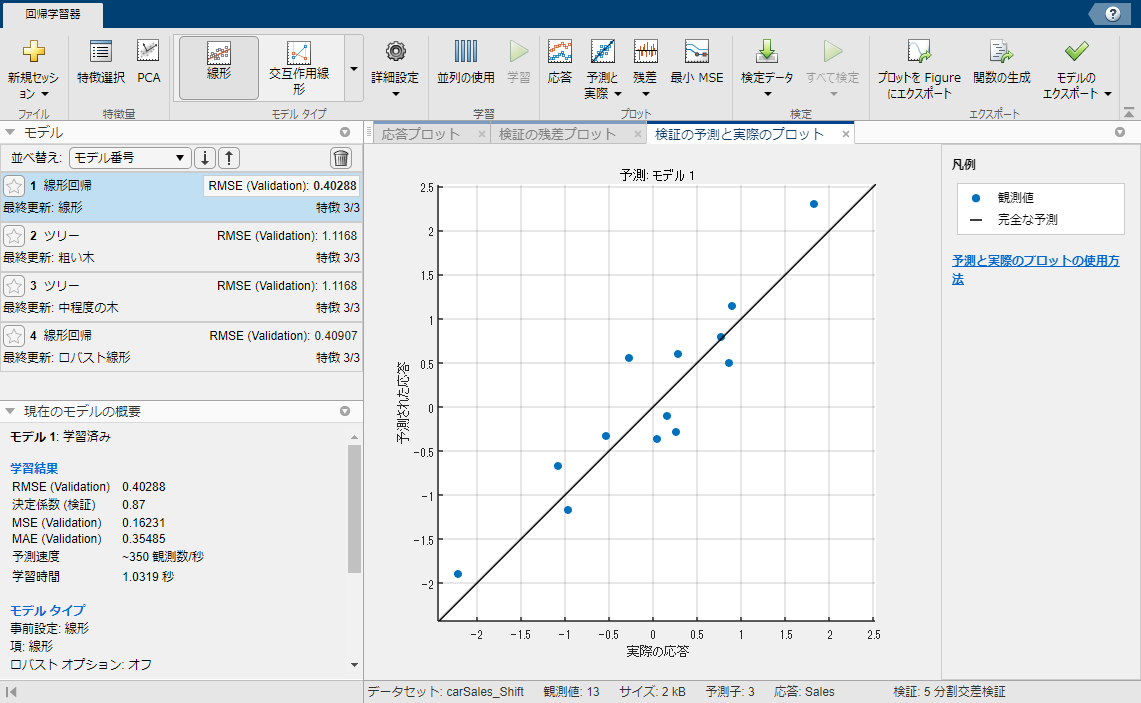

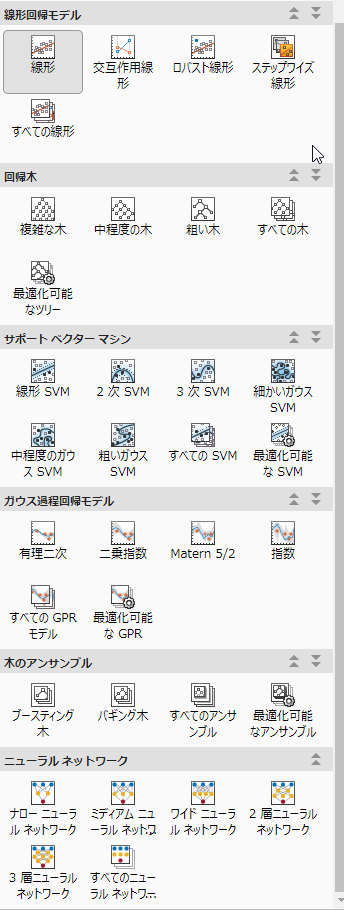

B: 

“Using this app, you can learn and evaluate the algorithms listed on the right all at once. ” 

* Copyright 2022 - 2023 The MathWorks, Inc *